## Lab1

G_num = [1];
G_denum = [720 1764 1624 735 175 21 1];

% G_m_num = G_num;
% G_m_denum = G_denum;
G_m_num = [1];
G_m_denum = [5 5 4 2];

Kp_r_m = 1;
Ki_r_m = 1;

Kp_r_k = 0.5;
Ki_r_k = 0.2;

t_amp = 0:0.5:10;
u_amp = 0:2:40;

out = sim("src\simulink_models\model_mfc.slx");

sys = tf(G_num, G_denum)

sys =
 
                               1
  ------------------------------------------------------------
  720 s^6 + 1764 s^5 + 1624 s^4 + 735 s^3 + 175 s^2 + 21 s + 1
 
Continuous-time transfer function.



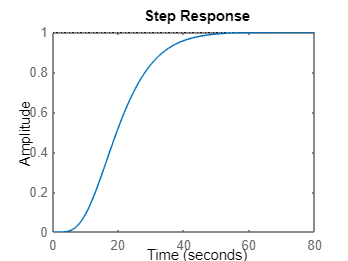

step(sys)

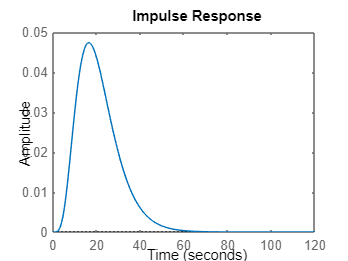

impulse(sys)

u = out.u_obiekt.signals.values(1:7000);
y = out.y_obiekt.signals.values(2:length(u) + 1);
t = out.y.time(1:7000);

U_matrix = zeros(length(u), length(u));
for i=1:length(u)
    for j=1:length(u)
        if i >= j
            U_matrix(i, j) = u(i - j + 1);
        end
    end
end

g = U_matrix\y;

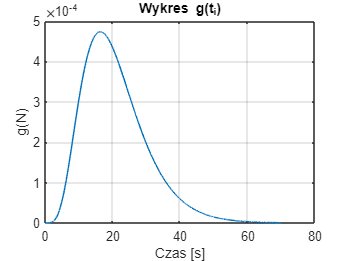

figure
plot(t, g)
xlabel('Czas [s]')
ylabel('g(N)')
title('Wykres g(t_i)')
grid on

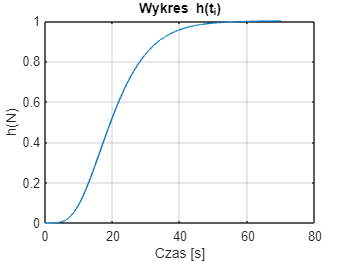


h = cumsum(g);
figure
plot(t, h)
xlabel('Czas [s]')
ylabel('h(N)')
title('Wykres h(t_i)')
grid on

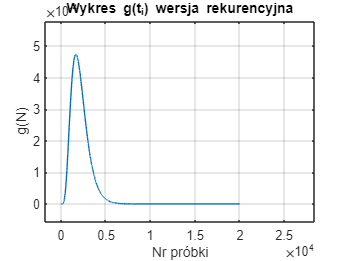

% u = out.u_obiekt.signals.values;
% y = out.y_obiekt.signals.values;
% g_new = zeros(length(u), 1);
% sum = 0;
% for i=2:length(u)-1
%     for j=1:i-1
%         sum = sum + u(j)*g_new(i-j);
%     end
%     g_new(i) = (y(i + 1) - sum)/u(52);
%     sum = 0;
% end
% 
% figure
% plot(g_new)
% xlabel('Nr próbki')
% ylabel('g(N)')
% title('Wykres g(t_i) wersja rekurencyjna')
% grid on

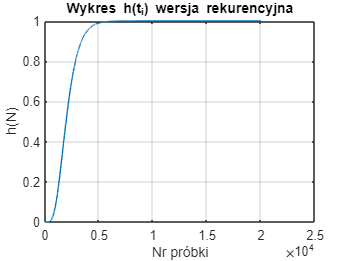

% 
% h_new_2 = cumsum(g_new);
% figure
% plot(h_new_2)
% xlabel('Nr próbki')
% ylabel('h(N)')
% title('Wykres h(t_i) wersja rekurencyjna')
% grid on

## Metoda Strejca 


%został wyznaczony punkt na podstawie wykresu odpowiedzi impulsowej 
y = h;
max_impulse = max(g)

max_impulse = 4.7335e-04

inflection_point_ind = find(g == max_impulse)

inflection_point_ind = 1644

ti = t(inflection_point_ind)

ti = 16.4000


% Oblicz pochodną numeryczną w tym punkcie (wykorzystując różnice skończone)
dt = t(2) - t(1);
dy_dt = gradient(y, dt);

% Oblicz współczynniki stycznej w tym punkcie
% a_tangent = dy_dt(inflection_point_ind)
a_tangent = 0.047

a_tangent = 0.0470

b_tangent = y(inflection_point_ind) - a_tangent * t(inflection_point_ind);
tangent_vec = a_tangent*t + b_tangent

tangent_vec =    -0.4120
   -0.4120
   -0.4119
   -0.4117
   -0.4115
   -0.4110
   -0.4106
   -0.4101
   -0.4096
   -0.4091


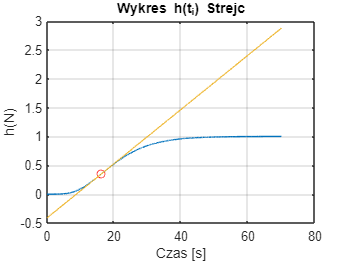

% na początku należy znaleźć punkt przegięcia 
y = h;
figure
plot(t, h)
xlabel('Czas [s]')
ylabel('h(N)')
title('Wykres h(t_i) Strejc')
grid on
hold on
plot(ti, h(inflection_point_ind), 'ro')
plot(t, tangent_vec)
hold off;